# Sistemas LTI Tests de controlabilidad.

### (Nota: algunas de las integraciones le pueden llevar un rato según con que ordenador estés trabajando, así que paciencia.)

Vamos a llevar a cabo los distintos tests de controlabilidad sugeridos en la teoría. Vamos a crear dos sistemas, uno controlable y otro no controlable:

Controlable:


$$$A_c =\pmatrix{1&2&0 \cr
-2&3&0\cr
1&0&-2}, \ B = \pmatrix{1& 2\cr
1&0\cr
0&0}$$


No controlable

#### 
$$$A_i =\pmatrix{1&2&0 \cr
-2&3&0\cr
0&0&-2}, \ B = \pmatrix{1& 2\cr
1&0\cr
0&0}$$


Ac = [1 2 0; -2 3 0; 1 0 -2];
B = [1 2;1 0;0 0]; %es comun a los dos sistemas
Ai = [1 2 0; -2 3 0; 0 0 -2];

#### Matriz de Controlabilidad,

Para construir la matriz de controlabilidad, se puede usar directamente en comando de matlab ctrb

Cc = ctrb(Ac,B)

Cc =      1     2     3     2     5    -6
     1     0     1    -4    -3   -16
     0     0     1     2     1    -2


Ci = ctrb(Ai,B)

Ci =      1     2     3     2     5    -6
     1     0     1    -4    -3   -16
     0     0     0     0     0     0


Por supuesto, podríamos hacerlo empleando la definición... 


$$\mathcal{C} = [B\ AB\ A^2B,\cdots,\  A^{n-1}B] $$


Mientras el sistema sea pequeño

cCc = [B Ac*B Ac^2*B]

cCc =      1     2     3     2     5    -6
     1     0     1    -4    -3   -16
     0     0     1     2     1    -2


Sabemos que el sistema será controlable si $\mathcal{C}$ tiene rango igual a la dimensión del sistema

rc = rank(Cc)

rc = 3

ri = rank(Ci)

ri = 2

Lo que confirma que el primer sistema es controlable y el segundo no

#### Test de Autovectores.

Un par $(A,B)$ es controlable si no existe ningún autovector de $A^T$en el kernel de $B^T$

Calculamos entonces los autovectores y autovalores de las matrices traspuestas de ambos sistemas

[avc,lc] = eig(Ac')

avc =    0.7071 + 0.0000i   0.7071 + 0.0000i  -0.2532 + 0.0000i
  -0.3536 - 0.6124i  -0.3536 + 0.6124i   0.1013 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9621 + 0.0000i


lc =    2.0000 + 1.7321i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   2.0000 - 1.7321i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i


[avi,li] = eig(Ai')

avi =    0.7071 + 0.0000i   0.7071 + 0.0000i   0.0000 + 0.0000i
  -0.3536 - 0.6124i  -0.3536 + 0.6124i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


li =    2.0000 + 1.7321i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   2.0000 - 1.7321i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 0.0000i


De aquí podemos aprender ya muchas cosas de ambos sistemas. Para empezar es bueno recordar que los autovalores de $A$ y $A^T$ son iguales

Por tanto, podemos estudiar la estabilidad de nuestros sistemas examinado los autovalores obtenidos. En ambos casos, obtenemos autovalores con parte real positiva, así que ninguno de los dos sistemas es estable.

Veamos ahora la controlabilidad con el test de autovectores. Podemos multiplicar $B^T$ por las matrices de autovalores que hemos obtenido:

testc = B'*avc

testc =    0.3536 - 0.6124i   0.3536 + 0.6124i  -0.1519 + 0.0000i
   1.4142 + 0.0000i   1.4142 + 0.0000i  -0.5064 + 0.0000i


testi = B'*avi

testi =    0.3536 - 0.6124i   0.3536 + 0.6124i   0.0000 + 0.0000i
   1.4142 + 0.0000i   1.4142 + 0.0000i   0.0000 + 0.0000i


Observamos que en el primer caso, todos los resultados son distintos de cero, por tanto no hay ningún autovector de $A_c^T$ en el kernel de $B^T$. Sin embargo el último autovector de $A_i^T$ da como resultado $0$ por tanto dicho autovector está en el kernel de $B^T$ y el segundo sistema no es controlable, como ya sabíamos.

Ojo, este test hay que pasarlo con cuidado para los casos en que tenemos autovalores repetidos, que tenga autovectores asociados con una multiplicidad geométrica mayor que uno. Hay que comprobar que no existe ningun vector en el espacio expandido por dichos autovectores que esté en el kernel de B

#### Test de Lyapunov para controlabilidad.

En este caso, debemos encontrar una solución $W\succ 0$ para la ecuación de Lyapunov:

 
$$AW+WA^T = -BB^T$$


Hay que recordar, que esta ecuación solo se cumple en el caso de que $A$ sea una matriz de estabilidad (Kurwith), ninguno de nuestros sistemas lo cumple, por lo que no debemos encontrar la solución deseada. Para comprobarlo, empleamos el comando de matlab lyap,

W = lyap(Ac,B*B')

W =    -1.2857   -0.6071    0.0238
   -0.6071   -0.5714    0.6548
    0.0238    0.6548    0.0119


lW = eig(W)

lW =    -1.7118
   -0.6307
    0.4973


La matriz obtenida $W$ no es definida positiva, el sistema no es estable y por eso no obtenemos solución adecuada para la ecuación de Lyapunov. Para comprobar que sí funciona para un sistema estable, vamos a definir una nueva matriz $A_e$


$$A_e = \pmatrix{-1 &-2& -1\cr
0&-1 &-1\cr
1&-2&-2}$$


Ae = [-1 2 -1; 0 -1 -1;1 -2 -2]

Ae =     -1     2    -1
     0    -1    -1
     1    -2    -2


lAe = eig(Ae) %estable

lAe =   -3.0000 + 0.0000i
  -0.5000 + 0.8660i
  -0.5000 - 0.8660i


rank(ctrb(Ae,B)) %controlable

ans = 3

Por tanto la matriz $A_e$ es una matriz de estabilidad y el par $(A_b,B)$ es controlable. Veamos qué dice ahora el test de Lyapunov,

W = lyap(Ae,B*B')

W =     4.5000    1.1923    0.3846
    1.1923    0.7564   -0.2564
    0.3846   -0.2564    0.4487


lp = eig(W)

lp =     0.0656
    0.7719
    4.8676


Todos los autovalores son positivos, lo que implica que  es definida positiva

Podemos obtener también W calculando el gramiano 'infinito'. Recordad que el gramiano 'infinito' es la única solución al test de Lyapunov de estabilidad.


$$W = \int_0^\inf e^{A\tau}BB^Te^{A^T\tau}d\tau$$


definimos una funcion con el gramiano (ver final del archivo)

f=@(t)dgramr(t,Ae,B); %handle a la funcion

Usamos el comando de matlab integral(f,t0,t1,'ArrayValued',1) el parámetro 'ArrayValued' hay que incluirlo y darle valor 1 para que sepa que el integrando tiene una matriz. De no hacerlo obtendremos un error.

W = integral(f,0,inf,'ArrayValued',1)

W =     4.5000    1.1923    0.3846
    1.1923    0.7564   -0.2564
    0.3846   -0.2564    0.4487


lW = eig(W)

lW =     4.8676
    0.0656
    0.7719


Por supuesto, obtenemos el mismo resultado que empleando la funcion lyap.

Volvamos a los dos sistemas del principio, el primero debería ser estabilizable, por realimentación de estados, empleando la ecuación de lyapunov. El segundo, no ya que no es posible encontrar una matriz W que cumpla con el test de Lyapunov, para el sistema realimentado. 

Sabemos que podemos estabilizar el sistema, empleando un parametro $\mu>0$. Para ello debemos encontrar una matriz $P\succ0$ de modo que satisfaga la ecuación de Lyapunov, 


$$P(A-BK)+(A-BK)^TP=-2\mu P$$


Para ello, empezamos por resolver la ecuación de Lyapunov


$$(-\mu I-A)W+W(-\mu I -A)^T = -BB^T$$


Vamos a elegir, por ejemplo $\mu=3$ Se debe elegir mayor que el menor autovalor  de $A_c$ (parte real), tomado en valor absoluto,  si no el sistema no será estable y no habrá solución para la ecuación de Lyapunov definida positiva (puede no haber solución en absoluto).

mu = 3;
W = lyap(-mu*eye(3)-Ac,B*B')

W =     0.5357    0.1786   -0.0870
    0.1786    0.1429   -0.0504
   -0.0870   -0.0504    0.0870


lW = eig(W)

lW =     0.0556
    0.0868
    0.6232


Definida positiva por los pelos... Si lo queremos más robusto, es cuestión de tomar una $\mu$ mayor...

Ahora tomamos $P = W^{-1}$ y la ganancia de nuestra realimentación será $K = \frac{1}{2}B^TP$

P = W^-1;
K = B'*P/2

K =    -0.2098    4.6341    2.4732
    3.2878   -3.7073    1.1415


Podemos comprobar donde quedan nuestros autovalores en lazo cerrado,

lAccl = eig(Ac-B*K)

lAccl =   -3.0000 + 3.0138i
  -3.0000 - 3.0138i
  -3.0000 + 0.0000i


Todos con parte entera negativa menor o igual a $-\mu$

Vamos a obtener los estados del sistema en función del tiempo para una condicíón inicial arbitraria, Para ello, creamos una función para el sistema real, en la que hemos cambiado la entrada $u$ por la ganancia $K$ (ver al final del archivo)

sys = @(t,x)sistema_lineal(t,x,K,Ac,B);
tf = 10;
x0 = [1;-3;2];
opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0,opciones);
figure(1)

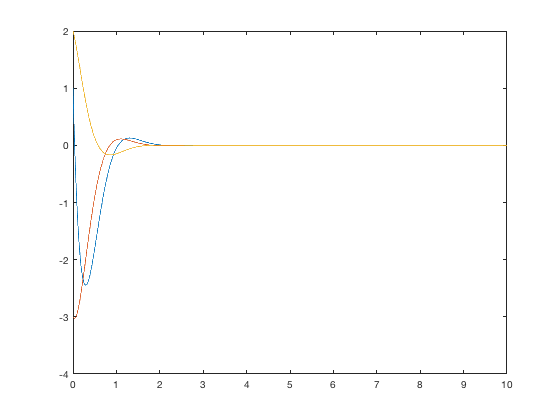

plot(t,x)

Podemos emplear, con identicos resultados, los objetos de matlab para sistemas lineales. Creamos un sistema completo con el comando ss Pero, ojo, le damos ya la matriz en lazo cerrado, (ojo a las dimensiones de C y D, no sirven para nada en nuestro caso pero deben ser coherentes con el tamaño del sistema.

sys = ss(Ac-B*K,B,eye(3),[0 0; 0 0; 0 0])


sys =
 
  A = 
           x1      x2      x3
   x1  -5.366    4.78  -4.756
   x2   -1.79  -1.634  -2.473
   x3       1       0      -2
 
  B = 
       u1  u2
   x1   1   2
   x2   1   0
   x3   0   0
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.



Podemos ahora simular la respuesta del sistema para las mismas condiciones iniciales de antes, empleando el comando initial de matlab

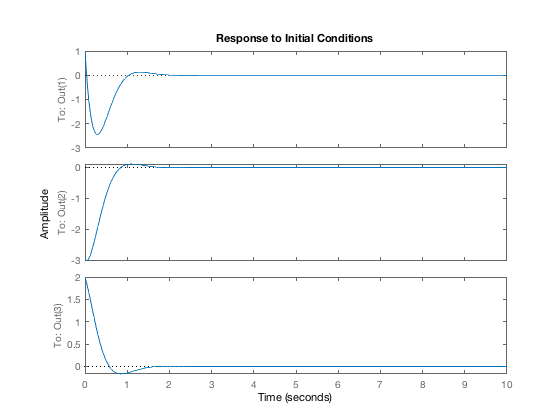

initial(sys,x0,tf)

Por último podemos emplear el comado de matlab place para poner los autovalores del sistema $A_c,\ B$ donde nos dé la gana, (recordad que place puede dar lugar a resultados mal condicionados y hay que manejarlo con cautela)

Primero definimos un vector con los valores deseados.

lambda = [-1,-2,-3];
K = place(Ac,B,lambda)

K =    -2.0000    6.0000         0
    2.0000   -2.0000         0


lAccl = eig(Ac-B*K)

lAccl =    -2.0000
   -3.0000
   -1.0000


En este caso place los ha colocado bastante bien.

Podemos volver a simular para ver como evolucionan los estados en el tiempo

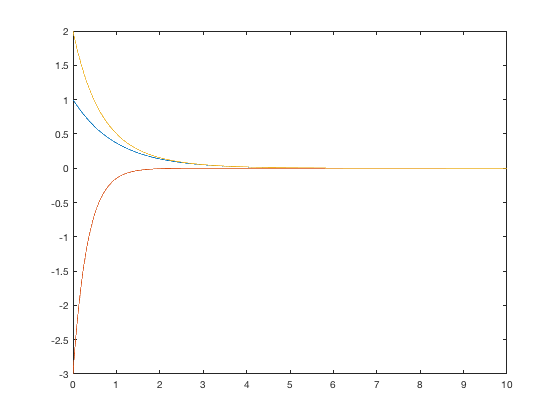

sys = @(t,x)sistema_lineal(t,x,K,Ac,B);
tf = 10;
x0 = [1;-3;2];
opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0,opciones);
figure(1)
plot(t,x)

Como todos los autovalores son ahora reales, no se observa sobreoscilación en la evolución de los estados.

function  dwr= dgramr(t,A,B)
%esta función permite construir el valor del integrando del grammiano de
%alcanzabilidad para un par A,B y un tiempo final t1,tiempo inicial t0=0
%si creamos un handle f = @(t)gramr(t,t1,A,B) in lo pasamos a la funcion de
%matlab integral, obtenemos el valor de gramiano Wr(t1,0)
dwr = expm(A*(t))*B*B'*expm(A'*(t));
end

function xdot = sistema_lineal(t,x,K,A,B)
%modificamos el sistema lineal para ponerlo en modo realimentación
u = -K*x;
xdot = A*x+B*u;
end